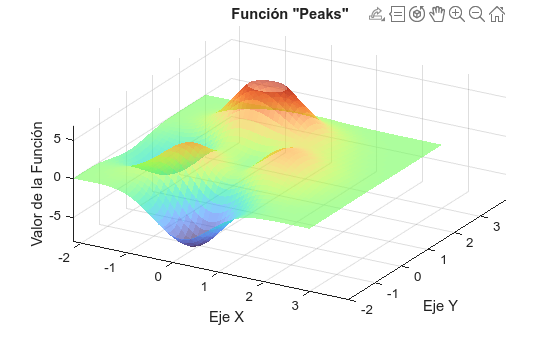

% ============================================================
% APLICACIÓN DEL ALGORITMO HILL CLIMBING CON MULTIPLES ÓPTIMOS
% Prof. Aboud BARSEKH-ONJI (D.Sc.)
% Email: aboud.barsekh@anahuac.mx
% https://orcid.org/0009-0004-5440-8092
% Universidad Anáhuac México Sur - Facultad de Ingeniería 
% ============================================================

% 1. Definición de la Función Objetivo
% Usamos una función más compleja con varios óptimos locales.
% La función 'peaks' de MATLAB es ideal para este ejemplo.
funcion_objetivo = @(x, y) 3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ...
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ...
   - 1/3*exp(-(x+1).^2 - y.^2);
% 2. Parámetros del Algoritmo 
limite_x = [-3, 3]; % Límites para el eje x
limite_y = [-3, 3]; % Límites para el eje y
tamano_paso = 0.05; % Un paso más fino para esta función compleja
max_iteraciones = 200;

% Visualizar la función
figure
hold on;
grid on;
title('Función "Peaks"');
xlabel('Eje X');
ylabel('Eje Y');
zlabel('Valor de la Función');
view(30, 45);

% Graficamos la superficie de la función
[x, y] = meshgrid(limite_x(1):0.1:limite_x(2), limite_y(1):0.1:limite_y(2));
z = funcion_objetivo(x, y);
surf(x, y, z, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
colormap("turbo");


% 2. Parámetros del Algoritmo 
limite_x = [-3, 3]; % Límites para el eje x
limite_y = [-3, 3]; % Límites para el eje y
tamano_paso = 0.05; % Un paso más fino para esta función compleja
max_iteraciones = 200;

% 3. Inicialización
% Empezamos en un punto aleatorio. La ubicación de inicio es CRÍTICA.
% Prueba cambiando el punto de inicio para ver cómo cae en diferentes óptimos.
% punto_actual_x = -0.5; punto_actual_y = -1.5; % Este inicio lleva a un óptimo local
punto_actual_x = limite_x(1) + (limite_x(2) - limite_x(1)) * rand();
punto_actual_y = limite_y(1) + (limite_y(2) - limite_y(1)) * rand();
valor_actual = funcion_objetivo(punto_actual_x, punto_actual_y);

% Guardamos el historial de puntos.
historial_puntos = [punto_actual_x, punto_actual_y, valor_actual];

% 4. Algoritmo Hill Climbing
disp('Iniciando búsqueda de Hill Climbing para función con múltiples óptimos...');

Iniciando búsqueda de Hill Climbing para función con múltiples óptimos...


for i = 1:max_iteraciones
    
    % Generamos los puntos vecinos
    vecinos = [punto_actual_x + tamano_paso, punto_actual_y; ...
               punto_actual_x - tamano_paso, punto_actual_y; ...
               punto_actual_x, punto_actual_y + tamano_paso; ...
               punto_actual_x, punto_actual_y - tamano_paso; ...
               punto_actual_x + tamano_paso, punto_actual_y + tamano_paso; ...
               punto_actual_x - tamano_paso, punto_actual_y - tamano_paso; ...
               punto_actual_x + tamano_paso, punto_actual_y - tamano_paso; ...
               punto_actual_x - tamano_paso, punto_actual_y + tamano_paso];

    % Evaluamos la función en los puntos vecinos
    valores_vecinos = funcion_objetivo(vecinos(:,1), vecinos(:,2));
    
    % Encontramos el mejor vecino
    [mejor_valor_vecino, indice_mejor] = max(valores_vecinos);
    mejor_vecino = vecinos(indice_mejor, :);

    % Se busca la maximización de la función
    if mejor_valor_vecino > valor_actual
        % Si el vecino es mejor, nos movemos
        punto_actual_x = mejor_vecino(1);
        punto_actual_y = mejor_vecino(2);
        valor_actual = mejor_valor_vecino;
        historial_puntos = [historial_puntos; punto_actual_x, punto_actual_y, valor_actual];
    else
        % Si no hay un vecino mejor, hemos llegado a un pico (local o global).
        disp('Se ha alcanzado un óptimo local. El algoritmo termina.');
        break;
    end
end

Se ha alcanzado un óptimo local. El algoritmo termina.



if i == max_iteraciones
    disp('Se alcanzó el número máximo de iteraciones.');
end

fprintf('Punto óptimo encontrado: (%.4f, %.4f) con valor = %.4f\n', ...
        punto_actual_x, punto_actual_y, valor_actual);

Punto óptimo encontrado: (1.2930, 0.0123) con valor = 3.5910


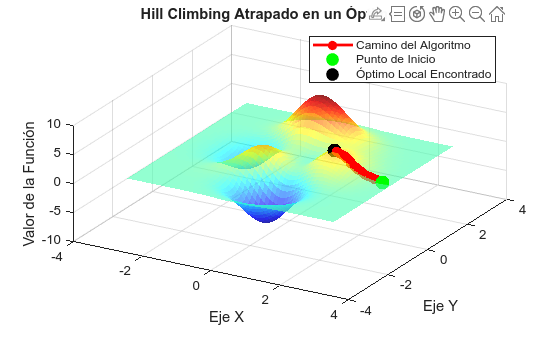



% 5. Visualización
figure
hold on;
grid on;
title('Hill Climbing Atrapado en un Óptimo Local');
xlabel('Eje X');
ylabel('Eje Y');
zlabel('Valor de la Función');
view(30, 45);

% Graficar la superficie de la función
[x, y] = meshgrid(limite_x(1):0.1:limite_x(2), limite_y(1):0.1:limite_y(2));
z = funcion_objetivo(x, y);
surf(x, y, z, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
colormap(jet);

% Graficar el camino que siguió el algoritmo
plot3(historial_puntos(:,1), historial_puntos(:,2), historial_puntos(:,3), ...
      'r-o', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 5);

% Marcar punto de inicio y el punto final
plot3(historial_puntos(1,1), historial_puntos(1,2), historial_puntos(1,3), ...
      'go', 'MarkerFaceColor', 'g', 'MarkerSize', 10);
plot3(historial_puntos(end,1), historial_puntos(end,2), historial_puntos(end,3), ...
      'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 10);

legend('', 'Camino del Algoritmo', 'Punto de Inicio', 'Óptimo Local Encontrado', 'Location', 'northeast');
hold off;